# Plot M3C Variables

% save('TestBench\Data\bufferNN.mat', 'buffer')

% name = 'summaryBCD';
% X = buffer.Tsim';
% X = [X, buffer.wy'];
% X = [X, buffer.ixy'];
% X = [X, buffer.ixy_ref'];
% X = [X, buffer.vc'];
% X = [X, buffer.ie'];
% X = [X, buffer.ie_ref'];
% X = [X, buffer.vo'];
% 
% [Nsamples, Nvars] = size(X);
% signalNames = {'Time', ...
%                'wy', ...
%                'iu', 'il', 'ia', 'ib', 'ic', ...
%                'iu_ref', 'il_ref', 'ia_ref', 'ib_ref', 'ic_ref', ...
%                'vc_ua', 'vc_ub', 'vc_uc', ...
%                'vc_la', 'vc_lb', 'vc_lc', ...
%                'ie1', 'ie2', ...
%                'ie1_ref', 'ie2_ref', ...
%                'vo'};
% T = array2table(X, 'VariableNames', signalNames);
% writetable(T, strcat(['TestBench\Data\', name,'.csv']));

## `vxy`

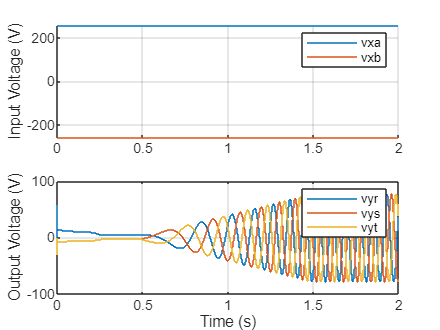

% abc

figure
subplot(2, 1, 1)
hold on
stairs(buffer.Tsim, buffer.vxy(1:buffer.p, :)')
hold off
if strcmp(buffer.Topology, 'M3C')
    legend('vxa', 'vxb', 'vxc')
elseif strcmp(buffer.Topology, 'M2C')
    legend('vxa', 'vxb')
end
ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.Tsim, buffer.vxy(buffer.p+1:end, :)')
legend('vyr', 'vys', 'vyt')
ylabel('Output Voltage (V)')
grid on
xlabel('Time (s)')

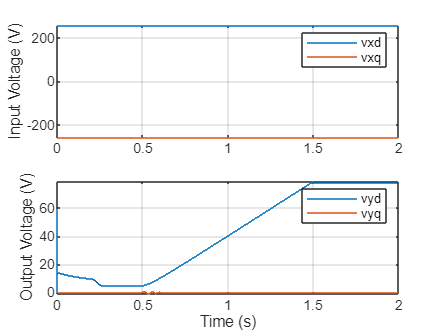


% dq

figure
subplot(2, 1, 1)
stairs(buffer.Tsim, buffer.vxdq')
legend('vxd', 'vxq')
ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.Tsim, buffer.vydq')
legend('vyd', 'vyq')
ylabel('Output Voltage (V)')
grid on

xlabel('Time (s)')

## Input PLL

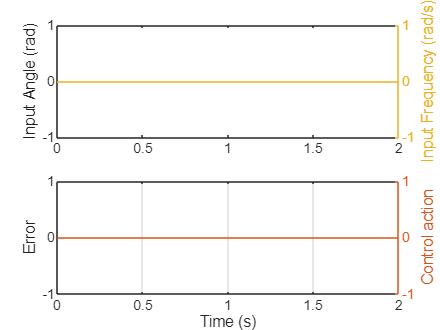

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.Tsim, buffer.gx')
hold on
stairs(buffer.Tsim, buffer.gx_pll', '--')
hold off
ylabel('Input Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.Tsim, buffer.wx')
hold on
stairs(buffer.Tsim, buffer.wx_pll', '--')
hold off
ylabel('Input Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.Tsim, buffer.ex_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.Tsim, buffer.ux_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Output PLL

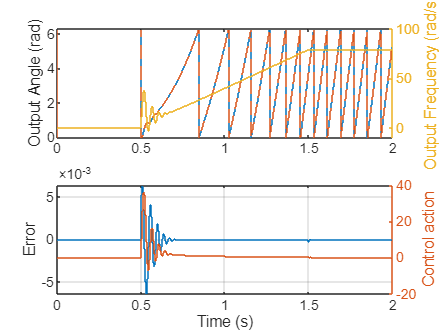

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.Tsim, buffer.gy')
hold on
stairs(buffer.Tsim, buffer.gy_pll', '--')
hold off
ylabel('Output Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.Tsim, buffer.wy')
hold on
stairs(buffer.Tsim, buffer.wy_pll', '--')
hold off
ylabel('Output Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.Tsim, buffer.ey_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.Tsim, buffer.uy_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## `vB`

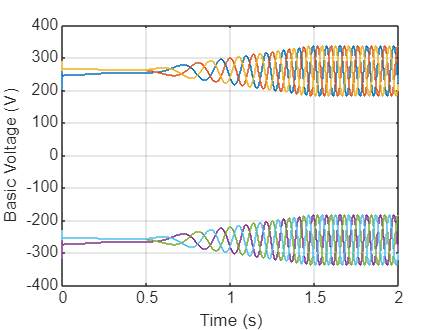

figure
stairs(buffer.Tsim, buffer.vB')
xlabel('Time (s)')
ylabel('Basic Voltage (V)')
grid on

## `vs`

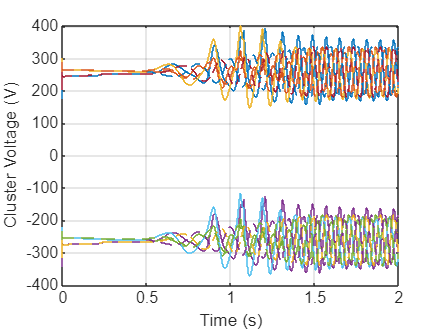

figure
stairs(buffer.Tsim, buffer.vs')
hold on
stairs(buffer.Tsim, buffer.vs_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## is

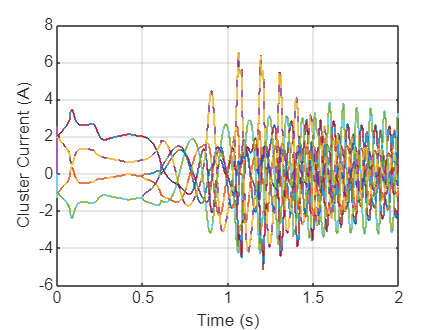

figure
stairs(buffer.Tsim, buffer.is')
hold on
stairs(buffer.Tsim, buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

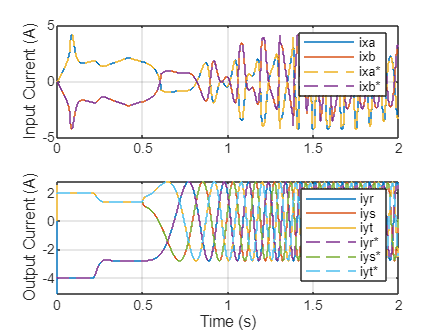

% abc

figure
subplot(2, 1, 1)
stairs(buffer.Tsim, buffer.ixy(1:buffer.p, :)')
hold on
stairs(buffer.Tsim, buffer.ixy_ref(1:buffer.p, :)', '--')
hold off
if and(buffer.p == 3, buffer.q == 3)
    legend('ixa', 'ixb', 'ixc', 'ixa*', 'ixb*', 'ixc*')
elseif and(buffer.p == 2, buffer.q == 3)
    legend('ixa', 'ixb', 'ixa*', 'ixb*')
end
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.Tsim, buffer.ixy(buffer.p+1:end, :)')
hold on
stairs(buffer.Tsim, buffer.ixy_ref(buffer.p+1:end, :)', '--')
hold off
legend('iyr', 'iys', 'iyt', 'iyr*', 'iys*', 'iyt*')
ylabel('Output Current (A)')
grid on
xlabel('Time (s)')

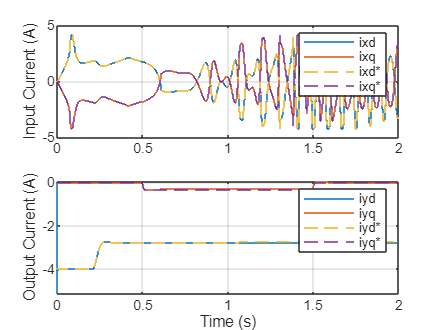


% dq

figure
subplot(2, 1, 1)
stairs(buffer.Tsim, buffer.ixdq')
hold on
stairs(buffer.Tsim, buffer.ixdq_ref', '--')
hold off
legend('ixd', 'ixq', 'ixd*', 'ixq*')
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.Tsim, buffer.iydq')
hold on
stairs(buffer.Tsim, buffer.iydq_ref', '--')
hold off
legend('iyd', 'iyq', 'iyd*', 'iyq*')
ylabel('Output Current (A)')
grid on

xlabel('Time (s)')

## `iB`

% figure
% stairs(buffer.Tsim, buffer.iB')
% hold on
% stairs(buffer.Tsim, buffer.iB_ref', '--')
% hold off
% xlabel('Time (s)')
% ylabel('Basic Current (A)')
% grid on

## `iz`

% figure
% stairs(buffer.Tsim, buffer.iz')
% hold on
% stairs(buffer.Tsim, buffer.iz_ref', '--')
% hold off
% xlabel('Time (s)')
% ylabel('Circulating Current (A)')
% grid on

## `Ec`

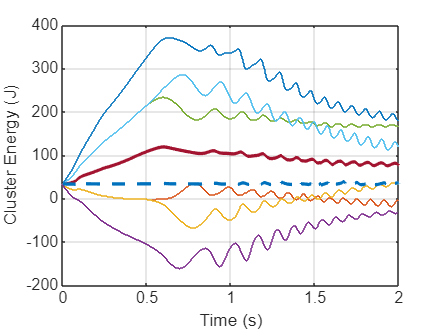

figure
stairs(buffer.Tsim, buffer.Ec')
hold on
stairs(buffer.Tsim, buffer.Ec_mean', 'LineWidth', 2)
stairs(buffer.Tsim, buffer.Ec_mean_filt', '--', 'LineWidth', 2)
hold off
ylabel('Cluster Energy (J)')
xlabel('Time (s)')
grid on

## TEB PI

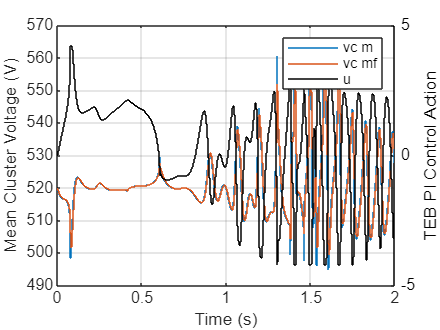

figure

stairs(buffer.Tsim, buffer.vc_mean')
hold on
stairs(buffer.Tsim, buffer.vc_mean_filt')
hold off
ylabel('Mean Cluster Voltage (V)')

yyaxis right
stairs(buffer.Tsim, buffer.u_TEB', 'Color', 'black')
ylabel('TEB PI Control Action')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

legend('vc m', 'vc mf', 'u')
xlabel('Time (s)')
grid on

## `vc`

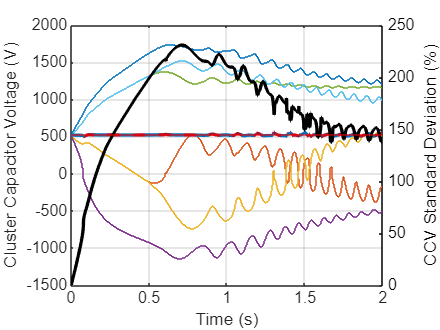

figure

stairs(buffer.Tsim, buffer.vc')
hold on
stairs(buffer.Tsim, buffer.vc_mean', 'LineWidth', 2)
stairs(buffer.Tsim, buffer.vc_mean_filt', '--', 'LineWidth', 2)
yline(buffer.vc_mean(1), 'Color', 'red')
hold off
ylabel('Cluster Capacitor Voltage (V)')

yyaxis right
stairs(buffer.Tsim, 100*std(buffer.vc./buffer.vc_mean)', 'LineWidth', 2, 'Color', 'black')
ylabel('CCV Standard Deviation (%)')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

xlabel('Time (s)')
grid on

## `ie`

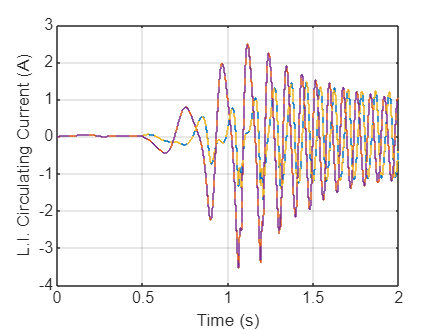

figure
stairs(buffer.Tsim, buffer.ie')
hold on
stairs(buffer.Tsim, buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vo`

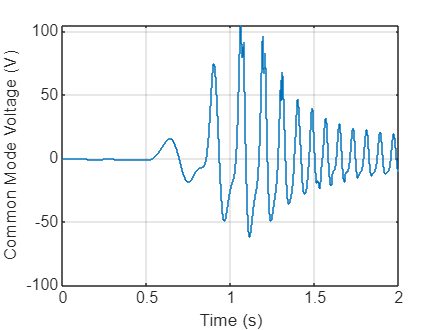

figure
stairs(buffer.Tsim, buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## w

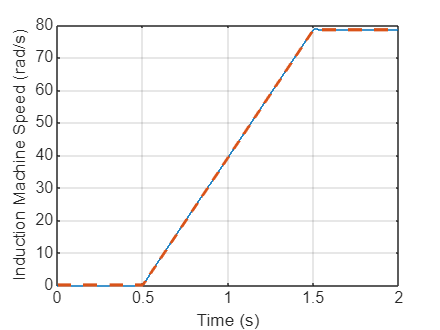

figure
stairs(buffer.Tsim, buffer.w')
hold on
stairs(buffer.Tsim, w_ref_vec', '--', 'LineWidth', 2)
hold off
xlabel('Time (s)')
ylabel('Induction Machine Speed (rad/s)')
grid on

## `Te`

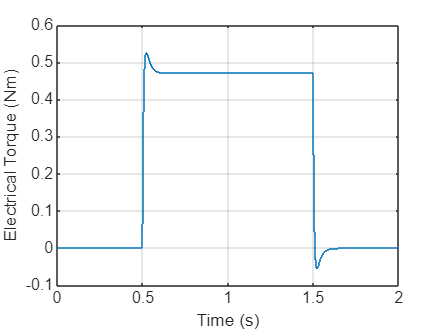

figure
stairs(buffer.Tsim, buffer.Te')
xlabel('Time (s)')
ylabel('Electrical Torque (Nm)')
grid on

## `ir`

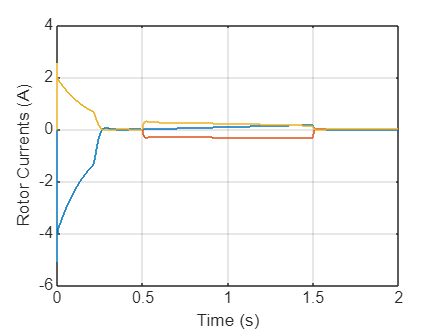

figure
stairs(buffer.Tsim, buffer.ir')
xlabel('Time (s)')
ylabel('Rotor Currents (A)')
grid on

## `Fr dq`

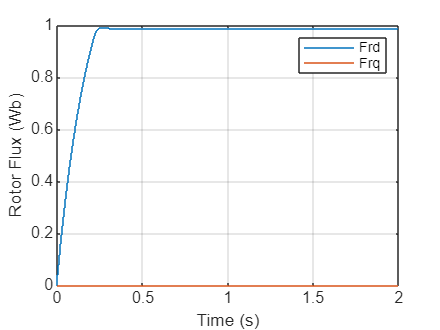

figure
stairs(buffer.Tsim, buffer.Fr_dq')
legend('Frd', 'Frq')
xlabel('Time (s)')
ylabel('Rotor Flux (Wb)')
grid on

## Cluster Energy Controller Stats

figure

% Optimality (exit flags, solver verbose)
subplot(2, 2, 1)
hold on
stairs(buffer.Tsim, buffer.exitflag_CEMPCi', '-')
stairs(buffer.Tsim, buffer.exitflag_CEMPCv', '--')
hold off
ylabel('Optimality')
legend('iz', 'vo')
grid on

% Active constraints
subplot(2, 2, 2)
hold on
stairs(buffer.Tsim, buffer.iA_CEMPCi', '-')
stairs(buffer.Tsim, buffer.iA_CEMPCv', '--')
hold off
ylabel('Active constraints')
legend('iz', 'vo')
grid on

% Execution time
subplot(2, 2, 3)
stairs(buffer.Tsim, buffer.Tex_CEMPC'*1000)
ylabel('Execution time (ms)')
grid on

% Optimal cost function
subplot(2, 2, 4)
stairs(buffer.Tsim, buffer.J_CEMPC')
ylabel('Optimal cost function')
grid on

sgtitle('ICB+LFOM controller')

## Cluster Current Controller Stats

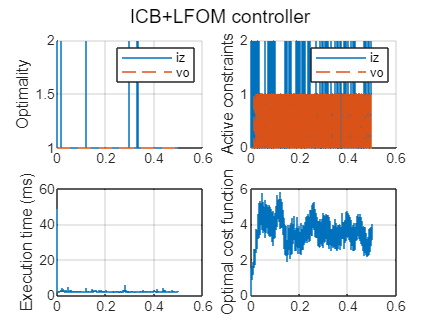

figure

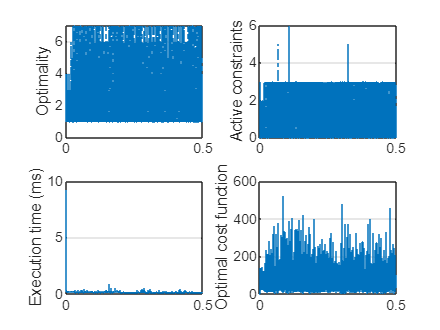


% Optimality (exit flags, solver verbose)
subplot(2, 2, 1)
stairs(buffer.Tsim, buffer.exitflag_CCMPC', '-.')
ylabel('Optimality')
grid on

% Active constraints
subplot(2, 2, 2)
stairs(buffer.Tsim, buffer.iA_CCMPC', '-.')
ylabel('Active constraints')
grid on

% Execution time
subplot(2, 2, 3)
stairs(buffer.Tsim, buffer.Tex_CCMPC'*1000)
ylabel('Execution time (ms)')
grid on

% Optimal cost function
subplot(2, 2, 4)
stairs(buffer.Tsim, buffer.J_CCMPC')
ylabel('Optimal cost function')
grid on

sgtitle('CC controller')